# A Tutorial for MIMO Modal Identification via FRVF

**Authors: **G. Dessena (Department of Aerospace Engineering, Universidad Carlos III de Madrid, Spain), M. Civera (Department of Structural, Geotechnical and Building Engineering, Politecnico di Torino, Italy), B. E. Bauret Martinez (Department of Aerospace Engineering, Universidad Carlos III de Madrid, Spain)

This live script reproduces the **noiseless** numerical case study of Section III in the reference article [1]: a 3-D cantilever beam identified in a non-square Multi-Input Multi-Output (MIMO) setting using Fast and Relaxed Vector Fitting (FRVF) with enhanced input stacking, benchmarked against the classical Least-Squares Complex Exponential (LSCE) method, with both identifications screened via stabilisation diagrams that automatically retain the highest stable model order.

This is an accompanying tutorial to [1] B. E. Bauret Martínez, G. Dessena, M. Civera, and O. E. Bonilla-Manrique, "Enhanced input stacking for non-square MIMO modal identification of aeronautical structures via Fast and Relaxed Vector Fitting," arXiv:2605.16037, 2026.

Tutorial folder structure:

**A note on attribution** — Fast and Relaxed Vector Fitting (FRVF) is not a new algorithm introduced by this work. The underlying Vector Fitting method, and the "fast" and "relaxed" refinements that give FRVF its name, are due to B. Gustavsen and co-authors (see References [3]–[5] below) and implemented in `vectfit3.m`, third-party code from SINTEF Energy Research. What this tutorial and the reference article [1] contribute is the enhanced input-stacking strategy that extends Vector Fitting to non-square Multi-Input Multi-Output (MIMO) systems.

**Requirements** — MATLAB with the Signal Processing Toolbox (for `modalfit` and `pwelch`, used by `lsce_fr.m`). Keep the repository folder structure intact so the `addpath` call below can find `Utilities/`. Beam-assembly and display-formatting helpers live in `Utilities/` rather than as local functions in this script — plain-text Live Code files do not support local function definitions.

**Licence** — the original code (root files and `Utilities/`) is released under the GNU General Public License v3.0. `vectfit3.m` (required by `FRVF.m`) is third-party code (B. Gustavsen, SINTEF) restricted to NON-COMMERCIAL use and is not bundled — see `Utilities/get_vectfit3.m` and the Licence section of README.md.

currentMLX = matlab.desktop.editor.getActiveFilename;
dummy = split(currentMLX, "/tutorial.mlx");
addpath(genpath(dummy{1}));
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
rng(42);

The line below checks for the third-party `vectfit3.m` dependency (non-commercial licence, not bundled — see `Utilities/get_vectfit3.m`) and guides you through obtaining it if missing.

get_vectfit3();

## 1. Beam model: material and cross-section

Cantilever beam, length $ L=2 $ m, rectangular hollow cross-section ($ b_{ext}=20 $ mm, $ h_{ext}=50 $ mm, wall thickness $ t=5 $ mm), aluminium ($ E=69 $ GPa, $ \rho=2700 $ kg/m$ ^3 $, $ \nu=0.3 $), discretised into $ N_{elem}=6 $ three-dimensional Euler–Bernoulli beam elements.

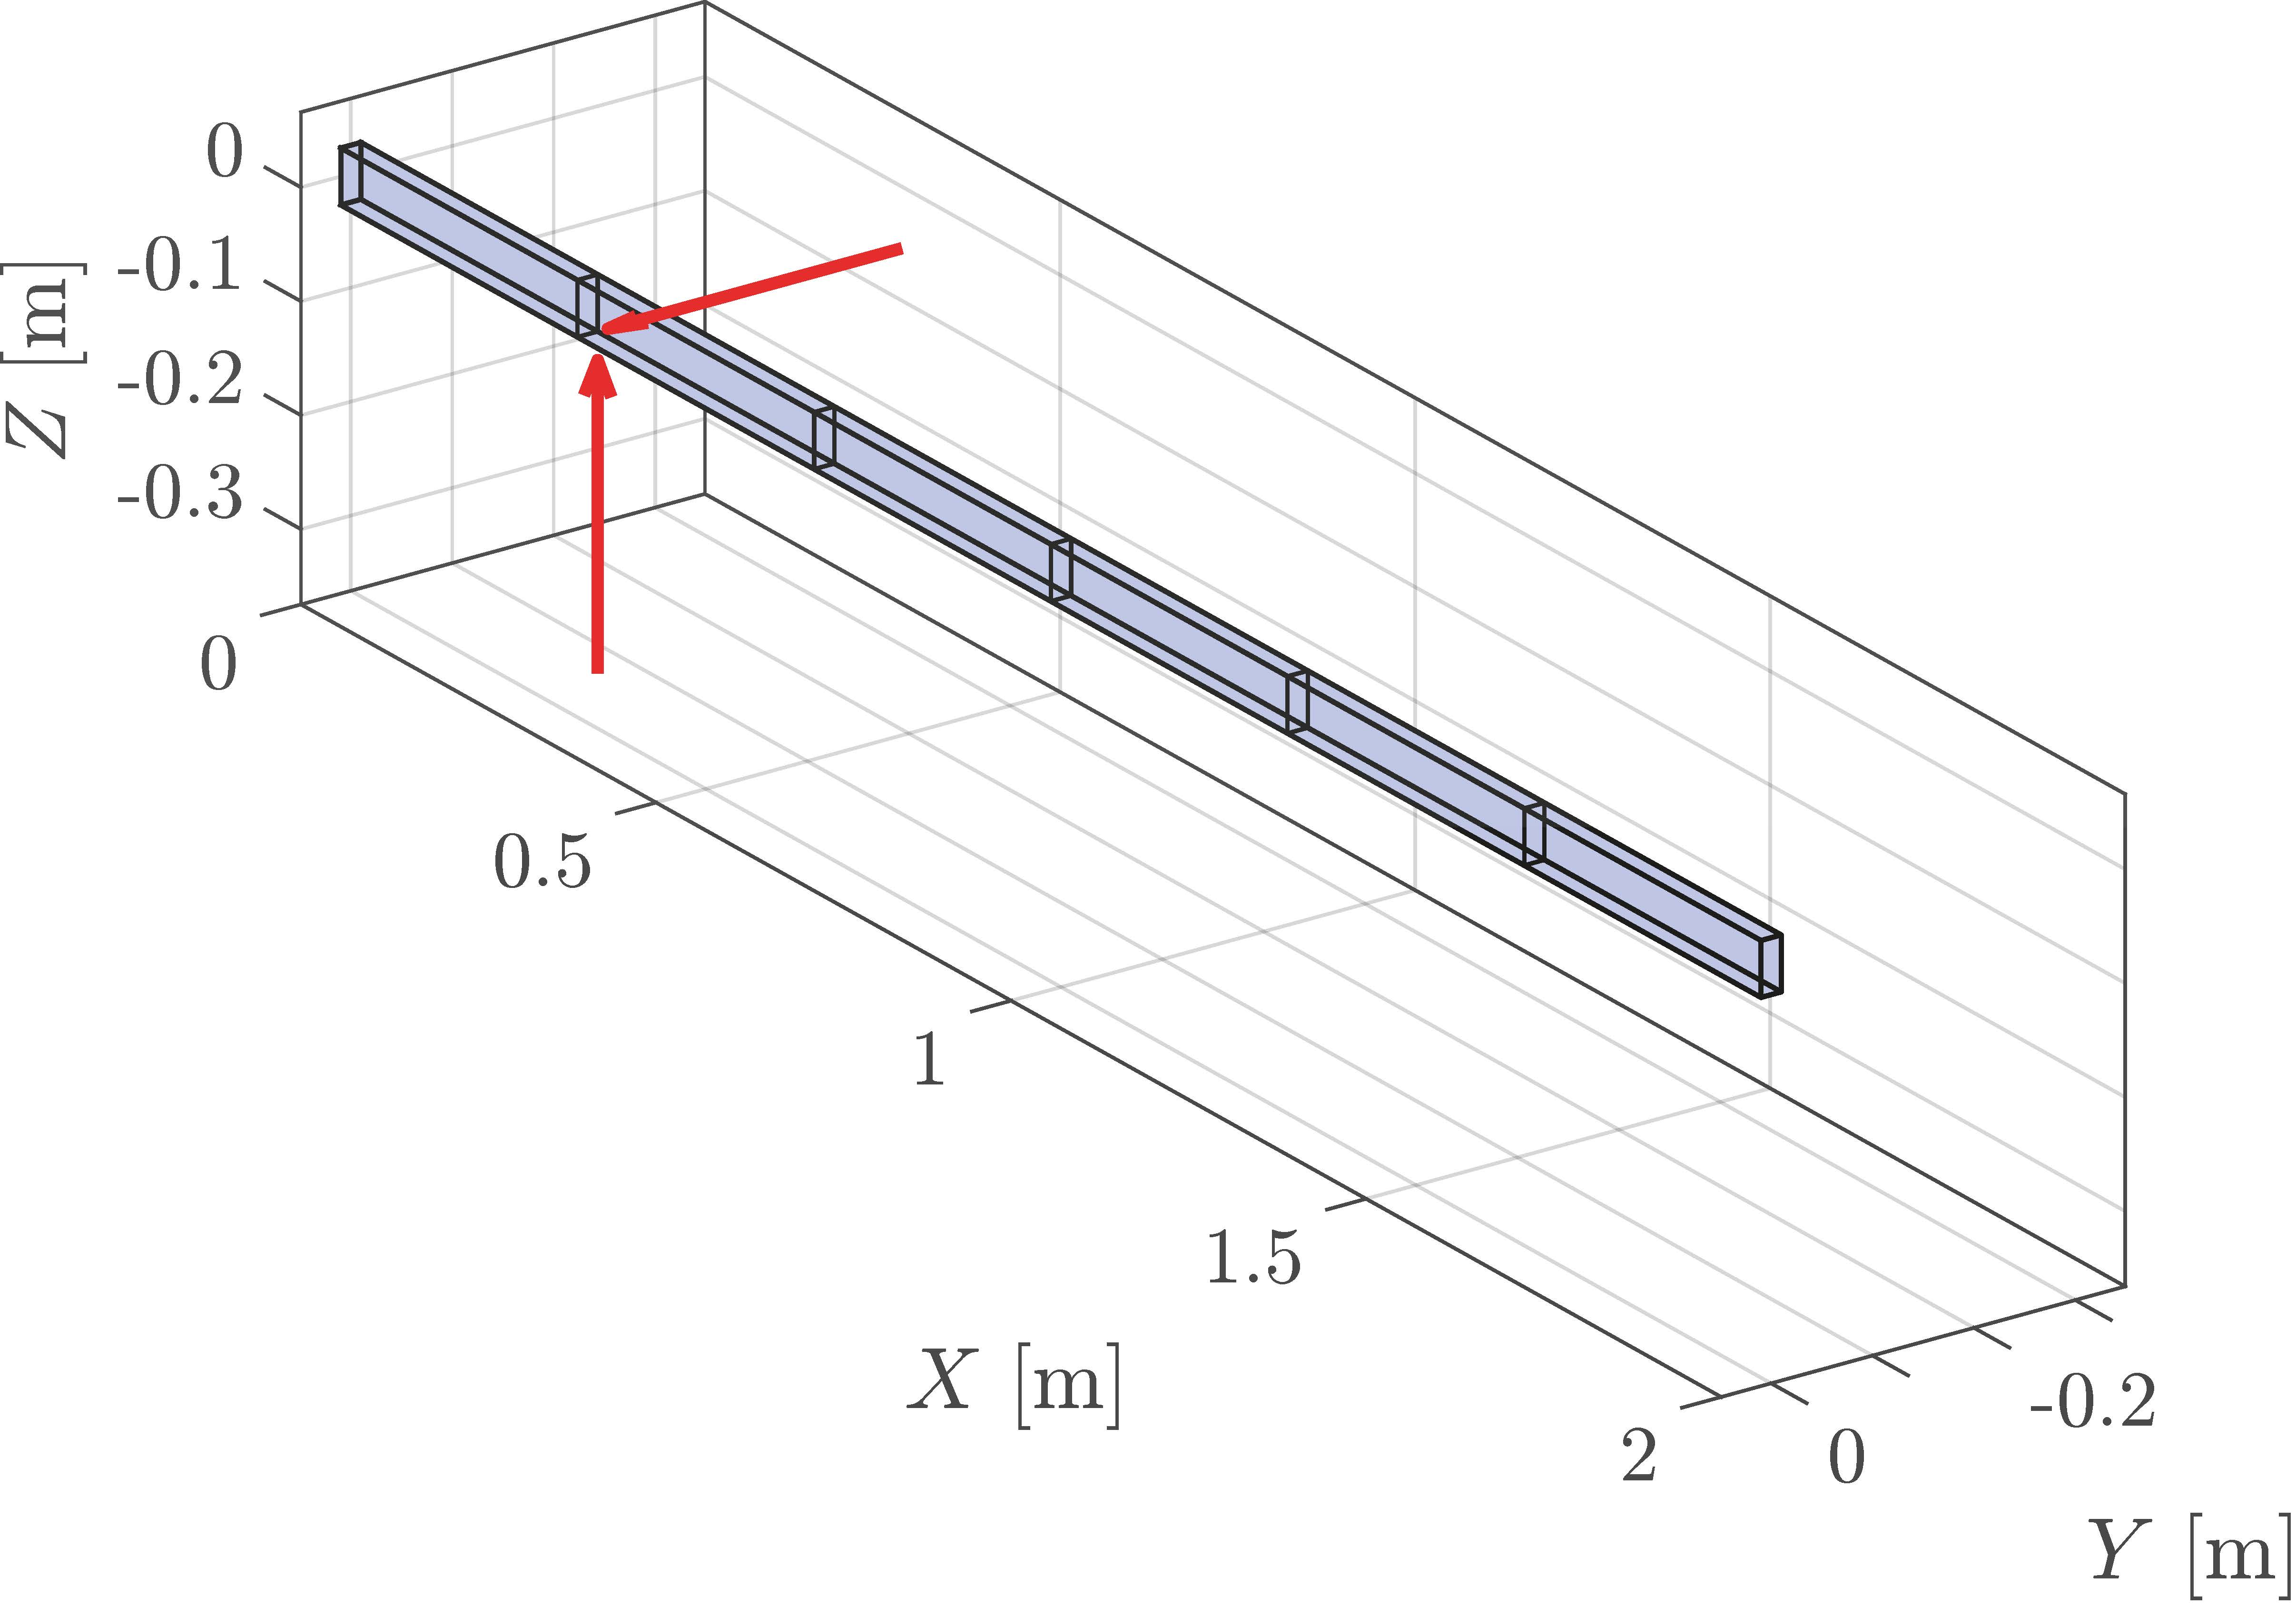

Figure 1. MIMO beam model with two excitation forces (retrieved from [1]).

b_ext = 0.02;
h_ext = 0.05;
t_w = 0.005;
b_int = b_ext - 2*t_w;
h_int = h_ext - 2*t_w;
A_xs = b_ext*h_ext - b_int*h_int;
Iz = (b_ext*h_ext^3 - b_int*h_int^3) / 12;
Iy = (h_ext*b_ext^3 - h_int*b_int^3) / 12;
E = 69e9;
rho = 2700;
nu = 0.3;
G = E / (2*(1+nu));
L = 2;
N_elem = 6;
fprintf('Cross-section : b=%.0f mm, h=%.0f mm, t=%.0f mm\n',b_ext*1e3,h_ext*1e3,t_w*1e3);
fprintf('A=%.4e m^2, Iz=%.4e m^4 (strong axis), Iy=%.4e m^4 (weak axis)\n',A_xs,Iz,Iy);

Cross-section : b=20 mm, h=50 mm, t=5 mm


fprintf('E=%.3g GPa, rho=%.0f kg/m^3\n',E/1e9,rho);

A=6.0000e-04 m^2, Iz=1.5500e-07 m^4 (strong axis), Iy=3.0000e-08 m^4 (weak axis)


E=69 GPa, rho=2700 kg/m^3


## 2. Finite element assembly

Axial and torsional degrees of freedom are excluded: in the Euler–Bernoulli formulation they are fully decoupled from the two bending planes, and are neither excited nor observed under the transverse-only loading applied here. Each free node therefore carries 4 DOFs, $ [u_y,\, u_z,\, \theta_y,\, \theta_z] $; with 6 free nodes this gives 24 free bending DOFs (12 strong-axis + 12 weak-axis modes), all inspectable.

[K_glob, M_glob] = assemble_beam(E, A_xs, Iy, Iz, rho, L, N_elem);
dof_free = 5 : size(K_glob, 1);
K = K_glob(dof_free, dof_free);
M = M_glob(dof_free, dof_free);
ndof = size(K, 1);
fprintf('FE model : %d elements, %d free DOFs (4/node, axial+torsion excluded)\n',N_elem,ndof);

FE model : 6 elements, 24 free DOFs (4/node, axial+torsion excluded)


## 3. Eigenanalysis: analytical reference modal parameters

The generalised eigenvalue problem on $ \mathbf{K},\mathbf{M} $ gives the analytical reference natural frequencies and mode shapes. Structural damping is assumed uncoupled, with a constant $ \zeta_n=3\% $ for every mode. The 12 output channels are the translational DOFs ($ u_y $ and $ u_z $ at each of the 6 free nodes); the lowest 10 modes (`Nmodes_report`) are reported below, matching Table I of the reference article.

[Phi, Lambda] = eig(full(K), full(M));
[omega2_sorted, idx] = sort(diag(Lambda));
omega_n = real(sqrt(omega2_sorted));
fn_an = omega_n / (2*pi);
Phi = Phi(:, idx);
Mn_vec = diag(Phi' * M * Phi);
zeta_val = 0.03;
zeta_an = zeta_val * ones(ndof, 1);
uy_dofs = 1 : 4 : ndof;
uz_dofs = 2 : 4 : ndof;
out_dofs = [uy_dofs, uz_dofs];
N_out = length(out_dofs);
mode_type = classify_modes(Phi, uy_dofs, uz_dofs, ndof);
fs = 1000;
f_nyq = fs / 2;
Nmodes_report = 10;
assert(fn_an(Nmodes_report) < f_nyq,'Mode %d (%.1f Hz) exceeds Nyquist (%.0f Hz).',Nmodes_report,fn_an(Nmodes_report),f_nyq);
phi_out = Phi(out_dofs, 1:Nmodes_report);
phi_out = phi_out ./ max(abs(phi_out), [], 1);
fprintf('  %4s  %10s  %10s  %-12s\n','#','fn [Hz]','zeta [-]','Type');
for ii = 1:ndof
    fprintf('  %4d  %10.3f  %10.4f  %-12s\n',ii,fn_an(ii),zeta_an(ii),mode_type{ii});
end

     #     fn [Hz]    zeta [-]  Type        


     1       5.001      0.0300  weak-axis   
     2      11.367      0.0300  strong-axis 
     3      31.347      0.0300  weak-axis   
     4      71.253      0.0300  strong-axis 
     5      87.912      0.0300  weak-axis   
     6     173.065      0.0300  weak-axis   
     7     199.826      0.0300  strong-axis 
     8     288.530      0.0300  weak-axis   
     9     393.383      0.0300  strong-axis 
    10     431.710      0.0300  weak-axis   
    11     655.838      0.0300  strong-axis 
    12     665.663      0.0300  weak-axis   
    13     914.317      0.0300  weak-axis   
    14     981.289      0.0300  strong-axis 
    15    1249.415      0.0300  weak-axis   
    16    1513.073      0.0300  strong-axis 
    17    1690.008      0.0300  weak-axis   
    18    2078.271      0.0300  strong-axis 
    19    2222.660      0.0300  weak-axis   
    20    2839.958      0.0300  strong-axis 
    21    3064.742      0.0300  weak-axis   
    22    3841.440      0.0300  strong-axis 
    23    

## 4. Time-domain simulation via modal superposition

Two simultaneous unit impulses (1 N, one sample long, at $ t=0 $) are applied at the first free node along $ y $ and $ z $ — the two physical MIMO inputs — and the response is propagated by modal superposition, sampled at $ f_s=1000 $ Hz for $ T=30 $ s.

Ts = 30;
dt = 1 / fs;
t_vec = 0 : dt : Ts;
Nt = length(t_vec);
in_dofs = [1; 2];
N_in = length(in_dofs);
f_ext = zeros(ndof, Nt);
for ii = 1:N_in
    f_ext(in_dofs(ii), 2) = 1;
end
f_modal = Phi' * f_ext;
wd = omega_n .* sqrt(max(1 - zeta_an.^2, 0));
q_modal = zeros(ndof, Nt);
for ii = 1:ndof
    if omega_n(ii) > 0 && omega_n(ii) < 2*pi*f_nyq
        h_ii = (1 / (Mn_vec(ii)*wd(ii))) .* exp(-zeta_an(ii)*omega_n(ii)*t_vec) .* sin(wd(ii)*t_vec);
        qc = conv(f_modal(ii,:), h_ii, 'full') * dt;
        q_modal(ii,:) = qc(1:Nt);
    end
end
x_phys = Phi * q_modal;
fprintf('Time simulation: Ts=%d s, fs=%d Hz, Nt=%d samples\n',Ts,fs,Nt);

Time simulation: Ts=30 s, fs=1000 Hz, Nt=30001 samples


## 5. Frequency Response Function computation

The non-square MIMO FRF tensor is formed directly from the FFTs of the simulated inputs and outputs, without any input-channel summation — the enhanced input-stacking of Algorithm 1 in [1] is performed internally by `FRVF_id.m`. The tensor is stored as $ [N_{out}\times N_{in}\times N_{freq}] $ for FRVF, and permuted to $ [N_{freq}\times N_{out}\times N_{in}] $ (MATLAB `modalfit` convention) for `lsce_fr.m`. A Welch PSD of the outputs is also computed here for the stabilisation-diagram overlay in Section 6.

in_sig = f_ext(in_dofs, :);
out_sig = x_phys(out_dofs, :);
signal = [in_sig; out_sig]';
N_pts = size(signal, 1);
freq_full = (0:N_pts-1) / (N_pts/fs);
X_full = fft(signal, N_pts) ./ N_pts;
cutOff = ceil(N_pts/2);
X = X_full(1:cutOff, :).';
freq_vec = freq_full(1:cutOff);
FRF = zeros(N_out, N_in, length(freq_vec));
for jj = 1:N_in
    for ii = 1:N_out
        FRF(ii, jj, :) = X(N_in+ii, :) ./ X(jj, :);
    end
end
FRF_lsce = permute(FRF, [3, 1, 2]);
NFFT = 6*4096;
[PSD_out, f_psd] = pwelch(out_sig', NFFT/2, NFFT/4, NFFT, fs);
fprintf('FRF tensor : [%d outputs x %d inputs x %d freq. points]\n',N_out,N_in,length(freq_vec));
fprintf('Freq. resolution : %.4f Hz, Nyquist : %.0f Hz\n',freq_vec(2)-freq_vec(1),f_nyq);

FRF tensor : [12 outputs x 2 inputs x 15001 freq. points]


Freq. resolution : 0.0333 Hz, Nyquist : 500 Hz


## 6. Order-sweep identification, stabilisation diagrams, and FRF fit quality

Both methods are swept over model orders 20:2:48 (FRVF) / equivalently 10:1:24 pole pairs (LSCE), and screened through `stabilisation_diagram.m` using the same stability thresholds as the reference article: frequency stability $ \Delta f<1\% $, damping stability $ \Delta\zeta<5\% $, mode-shape correlation MAC$ {}>0.95 $, and a global-repetition check requiring a candidate pole to reappear within $ \epsilon=2 $ Hz across at least `NumMAC`=3 orders. This stability screening is always computed by `stabilisation_diagram.m`, independently of interactivity; called here with `interactive = false`, it plots the diagram for each method and returns immediately without waiting for manual pole picking. The identification used for Table I (Section 7) is the stability-screened selection at the highest swept order — i.e. exactly what a human would see, and could click, on the top row of each diagram.

Separately, a single dedicated FRVF identification at the minimum order that can, in principle, capture all 10 reported modes ($ N_{order,min}=2\times10=20 $) is run purely to check FRF fit quality — a parsimonious order makes the strongest fit-quality demonstration. Its identified modal parameters are not reported anywhere; Table I uses the highest-order selection above instead.

nn_sweep = 20 : 2 : 48;
psdData.fr_axis = f_psd;
psdData.data = PSD_out;
psdData.chan = 1:N_out;
sp.d_max = 0.30;
sp.d_min = 1e-4;
sp.epsilon = 2;
sp.dfr = 0.01;
sp.dz = 0.05;
sp.dMAC = 0.95;
sp.NumMAC = 3;
sp.f_min = 0;
sp.f_max = f_nyq;
opts_vf.Niter1 = 5;
opts_vf.Niter2 = 5;
opts_vf.weightparam = 3;
opts_vf.asymp = 2;
opts_vf.stable = 1;
opts_vf.relaxed = 1;
opts_vf.nu = 1e-2;
fprintf('FRVF sweep...   ');
tic;

FRVF sweep...   

[sw_frvf, ~, ~] = FRVF_id(FRF, freq_vec, nn_sweep, opts_vf);
fprintf('%.1f s\n',toc);
fprintf('LSCE sweep...   ');

30.4 s


tic;

LSCE sweep...   

sw_lsce = lsce_fr(FRF_lsce, freq_vec, fs, nn_sweep/2);
fprintf('%.1f s\n',toc);
sysIDReduced_frvf = stabilisation_diagram(sw_frvf, "FRVF_beam_noiseless", 'stab', sp, psdData, '', "FRVF - noiseless beam", false, [], [], false);

2.1 s


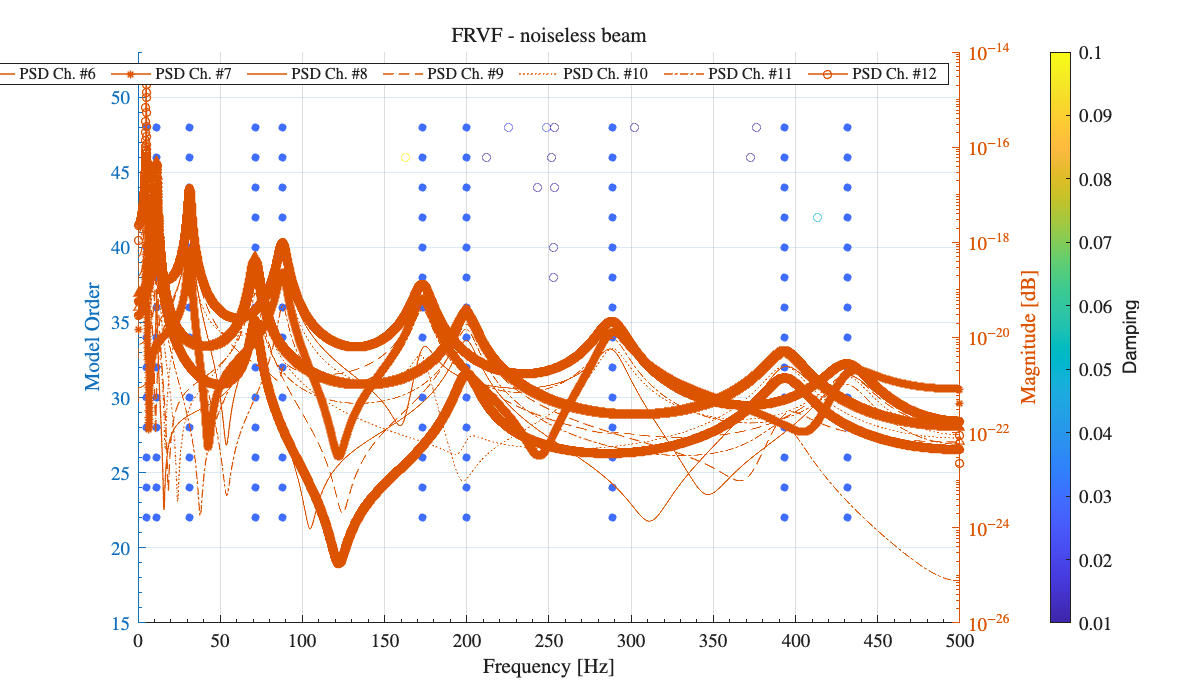

sysIDReduced_lsce = stabilisation_diagram(sw_lsce, "LSCE_beam_noiseless", 'stab', sp, psdData, '', "LSCE - noiseless beam", false, [], [], false);

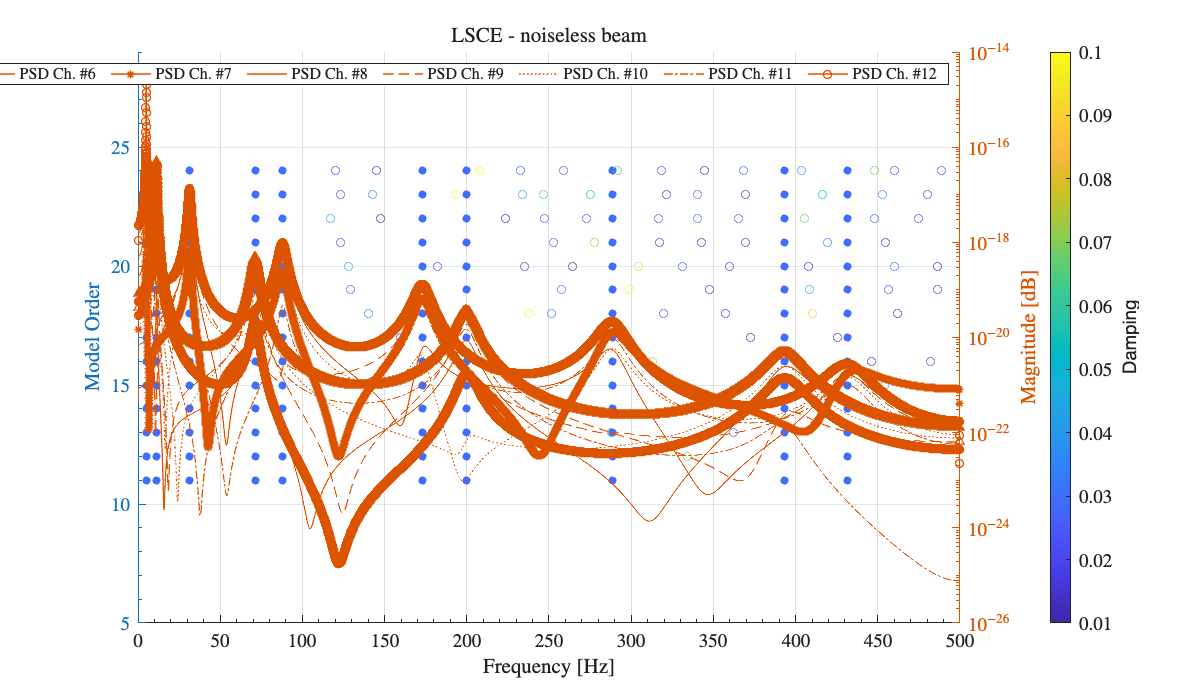

fn_frvf  = sysIDReduced_frvf(end).ident(1,:)';

z_frvf   = sysIDReduced_frvf(end).ident(2,:)';
phi_frvf = sysIDReduced_frvf(end).ident(3:end,:);
fn_lsce  = sysIDReduced_lsce(end).ident(1,:)';
z_lsce   = sysIDReduced_lsce(end).ident(2,:)';
phi_lsce = sysIDReduced_lsce(end).ident(3:end,:);
fprintf('FRVF: %d stable mode(s) at order %d.\n',numel(fn_frvf),sysIDReduced_frvf(end).order);
fprintf('LSCE: %d stable mode(s) at order %d.\n',numel(fn_lsce),sysIDReduced_lsce(end).order);

FRVF: 13 stable mode(s) at order 48.


N_order_min = 2 * Nmodes_report;

LSCE: 10 stable mode(s) at order 24.


fprintf('FRVF_id (minimum order, fit quality only)...   ');
tic;

FRVF_id (minimum order, fit quality only)...   

[~, ~, fit_min] = FRVF_id(FRF, freq_vec, N_order_min, opts_vf);
fprintf('%.3f s\n',toc);
f_stk = squeeze(sum(FRF,2));

4.572 s


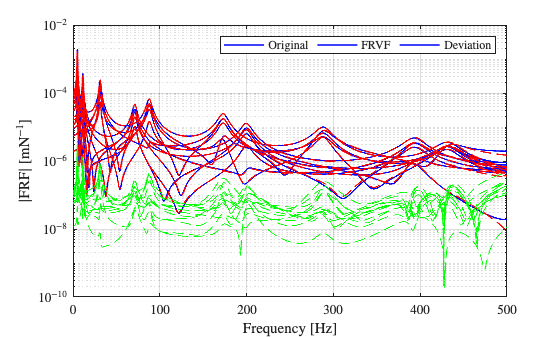

f_fit = fit_min.FRF_fit;
figure('Name','FRF fit quality');
semilogy(freq_vec, abs(f_stk), 'b', 'LineWidth', 1.2);
hold on;
semilogy(freq_vec, abs(f_fit), 'r--', 'LineWidth', 1.2);
semilogy(freq_vec, abs(sqrt((f_stk-f_fit).^2)), 'g--', 'LineWidth', 0.9);
hold off;
xlabel('Frequency [Hz]');
ylabel('$|$FRF$|$ [mN$^{-1}$]');
legend({'Original','FRVF','Deviation'},'Location','northeast','Orientation','horizontal');
xlim([0, f_nyq]);
grid on;

## 7. Table I: identified (highest stable order) vs analytical modal parameters

Natural frequency, damping ratio and MAC (against the analytical reference) for FRVF and LSCE, mode by mode, using the stability-screened identification at the highest swept order from Section 6. In the noiseless case both methods are expected to match the analytical values to within numerical precision, reproducing Table I of the reference article.

MAC_frvf = compute_mac(phi_out, phi_frvf);
MAC_lsce = compute_mac(phi_out, phi_lsce);
hdr = sprintf('%-3s %9s %7s | %-9s %5s %7s %5s | %-9s %5s %7s %5s','#','fn_an[Hz]','zeta','fn_FRVF','err%','zeta','MAC','fn_LSCE','err%','zeta','MAC');
fprintf('%s\n%s\n',hdr,repmat('-', 1, length(hdr)));
used_frvf = false(length(fn_frvf), 1);

#   fn_an[Hz]    zeta | fn_FRVF    err%    zeta   MAC | fn_LSCE    err%    zeta   MAC
-------------------------------------------------------------------------------------


used_lsce = false(length(fn_lsce), 1);
for ii = 1:Nmodes_report
    [str_f, used_frvf] = mode_match_str(fn_frvf, z_frvf, MAC_frvf, fn_an(ii), ii, used_frvf);
    [str_l, used_lsce] = mode_match_str(fn_lsce, z_lsce, MAC_lsce, fn_an(ii), ii, used_lsce);
    fprintf('%-3d %9.3f %7.4f | %s | %s\n',ii,fn_an(ii),zeta_an(ii),str_f,str_l);
end

1       5.001  0.0300 |     5.001 0.00%  0.0300  1.00 |     5.001 0.00%  0.0300  1.00
2      11.367  0.0300 |    11.367 0.00%  0.0300  1.00 |    11.367 0.00%  0.0300  1.00
3      31.347  0.0300 |    31.347 0.00%  0.0300  1.00 |    31.347 0.00%  0.0300  1.00
4      71.253  0.0300 |    71.253 0.00%  0.0300  1.00 |    71.253 0.00%  0.0300  1.00
5      87.912  0.0300 |    87.912 0.00%  0.0300  1.00 |    87.912 0.00%  0.0300  1.00
6     173.065  0.0300 |   173.065 0.00%  0.0300  1.00 |   173.065 0.00%  0.0300  1.00
7     199.826  0.0300 |   199.826 0.00%  0.0300  1.00 |   199.826 0.00%  0.0300  1.00
8     288.530  0.0300 |   288.530 0.00%  0.0300  1.00 |   288.530 0.00%  0.0300  1.00
9     393.383  0.0300 |   393.383 0.00%  0.0300  1.00 |   393.383 0.00%  0.0300  1.00
10    431.710  0.0300 |   431.710 0.00%  0.0300  1.00 |   431.710 0.00%  0.0300  1.00


## Conclusions

On the noiseless MIMO beam case, both FRVF and LSCE recover the 10 reported modes with negligible frequency and damping error and unit MAC against the analytical reference, using the stability-screened identification at the highest swept order (Section 6); the stabilisation diagrams show the same modes stabilising cleanly across model orders, which is the expected, best-case behaviour before noise is introduced. The FRF fit quality check (also Section 6) additionally shows that even the minimum-order FRVF model (order 20) already fits the FRF to several orders of magnitude below its amplitude, without needing the higher orders swept above.

## References

[1] B. E. Bauret Martínez, G. Dessena, M. Civera, and O. E. Bonilla-Manrique, "Enhanced input stacking for non-square MIMO modal identification of aeronautical structures via Fast and Relaxed Vector Fitting," arXiv:2605.16037, 2026. Preprint.

[2] B. E. Bauret Martínez, G. Dessena, M. Civera, and O. E. Bonilla-Manrique, "Multi-Input Multi-Output Fast and Relaxed Vector Fitting for Aircraft Ground Vibration Testing," Engineering Proceedings, vol. 133, no. 1, p. 162, 2026. doi: 10.3390/engproc2026133162.

[3] B. Gustavsen and A. Semlyen, "Rational approximation of frequency domain responses by Vector Fitting", IEEE Trans. Power Delivery, vol. 14, no. 3, pp. 1052-1061, 1999.

[4] B. Gustavsen, "Improving the pole relocating properties of vector fitting", IEEE Trans. Power Delivery, vol. 21, no. 3, pp. 1587-1592, 2006.

[5] D. Deschrijver, M. Mrozowski, T. Dhaene, D. De Zutter, "Macromodeling of Multiport Systems Using a Fast Implementation of the Vector Fitting Method", IEEE Microwave and Wireless Components Letters, vol. 18, no. 6, pp. 383-385, 2008.